Fs=1000;
 
t=0:1/Fs:1-1/Fs

t =          0    0.0010    0.0020    0.0030    0.0040    0.0050    0.0060    0.0070    0.0080    0.0090    0.0100    0.0110    0.0120    0.0130    0.0140    0.0150    0.0160    0.0170    0.0180    0.0190    0.0200    0.0210    0.0220    0.0230    0.0240    0.0250    0.0260    0.0270    0.0280    0.0290    0.0300    0.0310    0.0320    0.0330    0.0340    0.0350    0.0360    0.0370    0.0380    0.0390    0.0400    0.0410    0.0420    0.0430    0.0440    0.0450    0.0460    0.0470    0.0480    0.0490


 
s1=0.3 *sin (2*pi*30*t);
 
s2=0.7 * sin (2*pi*120*t);
 
s3=1 * sin (2*pi*200*t);
 
s=s1+s2+s3

s =          0    1.4865    1.3968    0.1123   -0.6580   -0.1687    0.5349    0.2873   -0.4625   -0.3162    0.9511    1.8473    1.0766   -0.6542   -1.4399   -0.5730    0.6514    0.7430   -0.0714   -0.3912    0.2351    0.6446   -0.2049   -1.5653   -1.7249   -0.3000    1.1356    1.0075   -0.3017   -1.0820   -0.5878    0.1357   -0.0779   -0.7807   -0.5762    0.7584    1.7290    1.0367   -0.6143   -1.3215   -0.3804    0.9115    1.0613    0.2938    0.0080    0.6542    1.0687    0.2092   -1.1760   -1.3740


 
n1=nextpow2(Fs)

n1 = 10

 
n=2^n1

n = 1024

 
f=fft(s,n)

f =    1.0e+02 *

  Columns 1 through 526


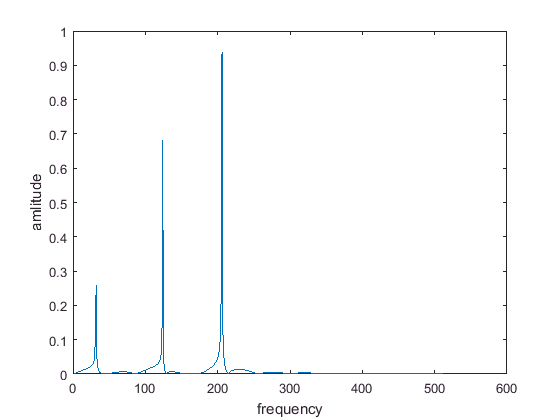

 
f=f(1:n/2);
 
l=length (s);
 
m=abs(2*f/l);
 
plot(m);
 
xlabel('frequency') % x-axis label
 
ylabel('amlitude') % y-axis label



% Fs = 1e6;
% Tm = 0.001;
% hwav = phased.FMCWWaveform('SampleRate',Fs,'SweepTime',Tm,'SweepDirection','Triangle','SweepBandwidth',1000000)
% xref = step(hwav);
% x_abs=real(xref);
% plot(x_abs)
% x = [zeros(20,1); xref(1:end-20)]
% plot(real(x))
% y = dechirp(x,xref)
% plot(real(y))
% 
% [Pxx,F] = periodogram(x,[],1024,Fs,'centered')
% plot(F/1000,10*log10(Pxx)); grid;
% xlabel('Frequency (kHz)');
% ylabel('Power/Frequency (dB/Hz)');
% title('Periodogram Power Spectral Density Estimate Before Dechirping');
% 
% [Pyy,F] = periodogram(y,[],1024,Fs,'centered');
% plot(F/1000,10*log10(Pyy));
% xlabel('Frequency (kHz)');
% ylabel('Power/Frequency (dB/Hz)');
% ylim([-100 -30]); grid
% title('Periodogram Power Spectral Density Estimate After Dechirping');